## Data analysis for Geoscience (GEO8026)

## Practical A2: Working with interval data (time, distance, etc) 

## A1.    Downloading and loading data from the internet

The following three commands reset the workspace by clearing all of the variables, closing all open Figures, and clearing the command line.

clear all; close all; clc;

Define the working folder that you are using. This should be the block 2 folder that you have downloaded from the GitHub repository:

folderIn = 'C:\_git_local\GEO8026\Block 02\';

Add this folder to the search path to ensure that all files and folders within it are visible to MATLAB:

addpath(genpath(folderIn));

Read the data into MATLAB. Note that two seperate lists of characters can be joined into one through the use of square brackets:  

C = readtable([folderIn 'data\h915a.csv']); 

For the purposes of this excercise we are only going to use the first 1000 measurements present within the data we have just loaded.

C = C(1:1000,:); % Extract the first 1000 measurements

## A2.    Managing different formats of date time

As the data that we are using is from a secondary source we are having to deal with the data in the format that they provide. This can sometimes be challenging when dealing with date time data. In this case the time data is provided with each component of the date time in a seperate column (i.e. [yyyy, mm, dd, HH]). This is closest to the [datevector](https://uk.mathworks.com/help/matlab/ref/datevec.html) format in MATLAB [yyyy, mm, dd, HH, MM, SS]  so we will modify the data so that it matches this format. You will note that the data is missing the minute (MM) and seconds (SS). For the purposes of this we will assume that they were collected at 0 min and 0 second i.e. on the hour (as we are using an hourly dataset). Let's get the data so that it matches the date vector format [yyyy, mm, dd, HH, MM, SS].

Extract the first four columns from table to double format - note the curly braces do the extraction from the table.

datetime_vector         = C{:,1:4}; 

Add a fifth and sixth column to represent the minutes and seconds (which were previously missing).

datetime_vector(:,5:6)  = 0; 

Now we have the data in a format that MATLAB recognises we can convert it to a range of different formats. Here we will convert it to `datetime`, `string`, `cell`, and `numeric`. These are useful for different purposes in MATLAB (as we will see later).

datetime            = datetime(datetime_vector); % convert the vector to datetime type
datetime_string     = datestr(datetime_vector); % convert the vector to a string type
datetime_cellstr    = cellstr(datetime_string); % convert the string type to cell type
datetime_numeric    = datenum(datetime_string); % convert the string type to numeric type

However, let's now look at an example where the dates is not in the vector format, but is instead a `cellstr` (view the `datetime_cellstr` variable to see). This is probably the most common format of datetime that you will come across. So let's try and load an example of this data into MATLAB and convert it to a numeric format.

D                   = readtable([folderIn 'data\h915a_datestr.csv']); 

Again, for the purposes of this excercise we are only going to use the first 1000 measurements present within the data we have just loaded. We can then convert to an appropriate datetime variable

D                   = D(1:1000,:); % Extract the first 1000 measurements
datetime2           = D{:,1}; % extract the data from the table (into datetime format)
datetime_cell2      = cellstr(datetime2); % convert to a cell type
datetime_numeric2   = datenum(datetime2); % option 1 - converting from datetime to numeric
datetime_numeric2   = datenum(datetime_cell2, 'dd/mm/yyyy HH:MM'); % option 2 - converting from cell to numeric

In some instances when we extract the datetime data from the table, the format will be of cell already rather than datetime, in which case we ommit the conversion from datetime to cell (the third command in the code snipped above).

## A3.    Checking for consistency in sample times

Now that we have both the datetime information and the sensor measurements into MATLAB, we can begin to check for consistency in the measurements. This is an important step in any data analysis as many methods will assume that measurements are made at equal intervals/increments. However this is not always the case and will depend on the type of data you are acquiring and the statistical methods being adopted. We can check for equal intervals/increments by checking the difference between numeric datetime values. These should be constant throughout:

dt = diff(datetime_numeric2); % calculate the difference between times

As the data is hourly, we would expect each measurement to have a time one-hour ahead of the previous one. To do this we first need to know what the numeric value is for one-hour. We can check this by subtracting datenum values of two times that are one hour appart:

dt_one_hour = datenum('11/09/2021 10:00:00','dd/mm/yyyy HH:MM:SS') - ...
    datenum('11/09/2021 09:00:00','dd/mm/yyyy HH:MM:SS');

This gives us a value of 0.0416666666278616 (displayed as 0.0417 in the workspace). We can then use this information to calculate the time difference (in hours) between each of the measurements. Below we see that the minimum and maximum difference between data points is one-hour. So there are no missing data points. Good news!

dt_hr       = dt./dt_one_hour;
dt_hr_min   = min(dt_hr);
dt_hr_max   = max(dt_hr);

Whilst the above code is specific for finding if there are gaps within timeseries data, similar commands can also be called where the data has been collected at intervals that are not time-based (e.g. distances). In order to do this, the `diff `command would be applied to the distance data and this would be compared against our expected increment.

## A4.    Finding missing observations

The previous case where there are no missing measurements is not necessarily realistic of data that you may be dealing with. Therefore we will randomly remove 75 datapoints from the array and run the test again. These are removed from both the datetime and measurement variables.

% Code block to remove 75 measurements at random
rem_idx     = randperm(numel(datetime_numeric2),75); % Randomly select 75 numbers 
keep_idx    = setdiff(1:numel(datetime_numeric2),rem_idx); %Find values present within the range and the rem_idx variable
dt_mod      = datetime_numeric2(keep_idx); % create a copy of the time variable but with 75 values removed
data_mod    = D{keep_idx,2}; % extract the measurement data with the 75 values removed

After removing the 75 measurements, `dt_mod` becomes the new numeric time variable, and `data_mod` the sensor measurements. Now, lets calculate the difference between measurement times:

dt2          = diff(dt_mod); % calculate the difference in numeric time between measurements
dt2_hr       = dt2./dt_one_hour; % calulcate this in hours
dt2_hr_min   = min(dt2_hr); % extract the maximum
dt2_hr_max   = max(dt2_hr); % extract the minimum

Here we can now see that the maximum difference between times is greater than one i.e. more than one hour. We can visualise this by creating a basic plot:

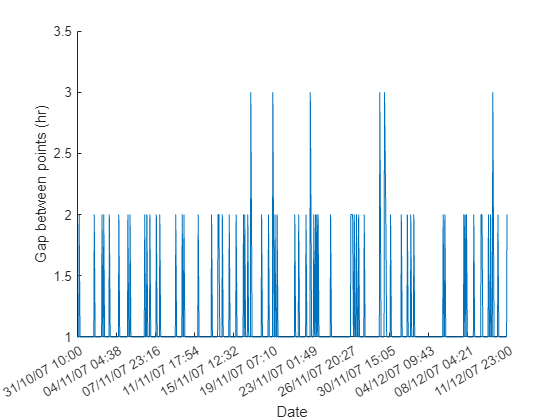

f1 = figure();
hold on;
ax1 = gca();
ax1.XTick = linspace(dt_mod(1),dt_mod(end-1),12); % this sets the x-axis so that there are 12 equally spaced labels
plot(dt_mod(1:end-1),dt2_hr); hold on;
datetick('x','dd/mm/yy HH:MM', 'keepticks');
xtickangle(ax1,30); % we can define the angle of the axis labels e.g. 30 degrees
ylabel('Gap between points (hr)');
xlabel('Date');

Now we can attempt to in-fill the missing data so that we once again have a continuous time series. We first need to identify what the time data should look like without any missing data. We can do this by creating a variable with a consistent time increment of one hour. We can use the variable we created previosuly called `dt_one_hour` to do this. We create a new variable spanning from the minimum time (i.e. first measurement) to maximum time (i.e. last measurement) in hourly steps.

time_good   = min(dt_mod):dt_one_hour:max(dt_mod); % note this is a 1xn array whereas the rest are nx1
time_good   = time_good'; % for consistency we transpose the data to create a nx1 array using an apostrophe after the variable name.

Next we compare the continuous time variable [`time_good]` with those of the time variable that has 75 values missing `[dt_mod]`. We can do this using the `knnsearch` command to find the nearest neighbours.

% idx is the index of dt_mod that is closest to time_good
% D is the distance between the values (in this case in numeric time).
[Idx,D]     = knnsearch(dt_mod,time_good);

Whilst this function is useful, it finds the closest times regardless of how far away they are from each other. Therefore we need to set a maximum threshold for this. In this instance I'm going to set the maximum allowable time difference as 1-minute.

% numeric value for one hour / 60 to gives the numeric value for one minute
one_min     = dt_one_hour./60; 

% find all measurements that were acquired within one minute of the
% required time and store them within data_good.
Idx_good            = find(D < one_min);
data_good(Idx_good) = data_mod;

However the data within `data-good `now contains zeros for the times when data had been removed. Lets visualise this:

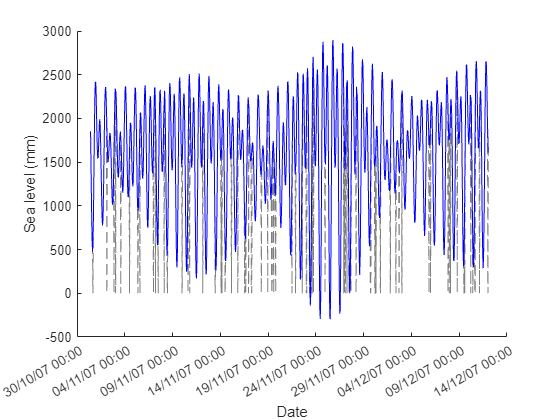

f0 = figure(); hold on
h1 = plot(time_good,data_good,...
    'Color', [0.5,0.5,0.5],...
    'LineStyle','--'); hold on; % first plot the complete data
h2 = plot(dt_mod,data_mod,...
     'Color', 'b',...
    'LineStyle','-'); % next plot the data with missing measurements
datetick('x','dd/mm/yy HH:MM', 'keepticks');
ylabel('Sea level (mm)');
xlabel('Date');

What you can see in the figure is that when we plot the continuous dataseries there are times when measurements are shown as being zero (grey dashed line). Conversely, when we plot the data with 75 measurements stripped out MATLAB joins the lines between points.

Neither the situation where we have data at unequal increments, or having zeros present is ideal as this may affect subsequent analyses. However, we have a few options of how to deal with this. We can either choose to set the missing data as `NaN` (not a number - which is treated as a blank), or we can interpolate the data using the data surrounding it. We will explore these options in the next section.

## A5.    Dealing with missing observations

We can simply replace all values that are zeros with NaN by executing the following commands:

y            = data_good'; % make a copy of data_good
zeros_idx    = find(y == 0); % finds the cell indexes for values of zero
y(zeros_idx) = NaN; % replaces these cells with NaN

% Lets visualise this
f2  = figure(); hold on; % create a new figure
ax1 = subplot(2,1,1); % subplots allow us to display multiple plots in one figure
h3  = plot(time_good,y,... % plot the time and measurements
    'Color', 'b',... % color set as blue
    'LineStyle','-'); hold on; % line as solid
set(ax1,'XTickLabel',[]); % remove the x-axis label for the top plot
ylabel('Sea level (mm)'); % set the y-axis label

Alternatively, we may wish to interpolate between these missing data points. 

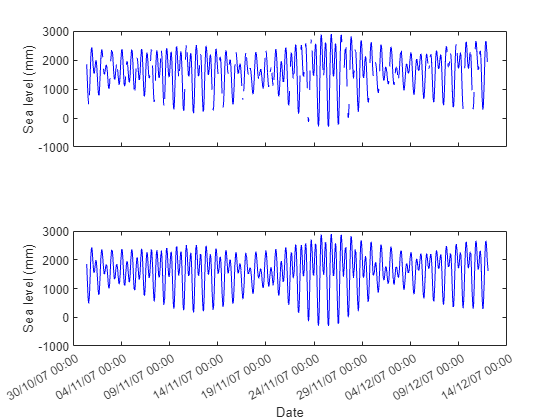

zeros_idx       = find(data_good == 0); % finds the cell indexes for values of zero
not_zero_idx    = find(data_good ~= 0); % finds the cell indexes for values of not zero
x               = time_good(not_zero_idx); % x = only non-zero data
y               = data_good(not_zero_idx)';% y = only non-zero data
missing_time    = time_good(zeros_idx); % measurement times that we want to interpolate
yi              = interp1(x,y,missing_time); % run linear interpolation

interp_y(not_zero_idx)  = data_good(not_zero_idx);
interp_y(zeros_idx)     = yi;
interp_y                = interp_y';

ax2 = subplot(2,1,2); % create a second subplot below the first
h4  = plot(time_good,interp_y,... % plot the measurements against time
    'Color', 'b',... % set color as blue
    'LineStyle','-'); hold on; % solid line

datetick('x','dd/mm/yy HH:MM', 'keepticks'); % set x-axis as date format
ylabel('Sea level (mm)'); % set y-axis label
xlabel('Date'); % set x-axis label

In the above, we used linear interpolation, but other methods may also be adopted for 1D data, including: 

% nearest neighbour: interp1(x,y,xi, 'nearest');
% cubic spline:  spline(x,y,xi);
% shape preserving: pchip(x,y,xi)

Or in some cases we may wish to use a combination of setting the data as `NaN`, and performing interpolation. For example, if you have a gap in your measurements of 1 data point, linear interpolation may be a nice option to fill in the gaps, whilst preserving the dynamics of the system quite well. However, what if we have a gap of more than one measurement? In this instance, interpolation will fill in the gaps, but the dynamics of the system are less likely to be preserved. Of course, the acceptable number of missing points for interpolation will depend on the variable being measured and the timestep between measurements. Let's explore how we can choose to interpolate between gaps of one, but set gaps of 2 or more as `NaN`:

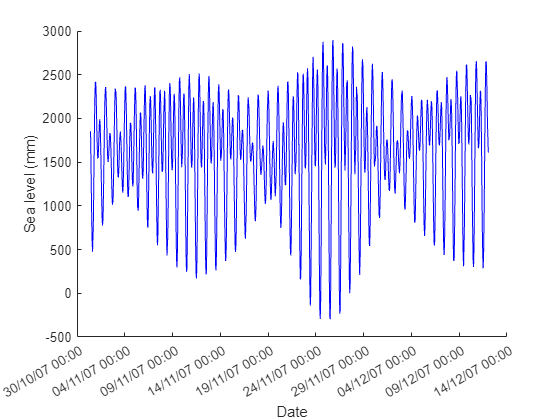

% First, let's set all data that we do not want to interpolate as NaN.
% Data that we will interpolate will be zero.

y               = data_good'; % make a copy of data_good
noDataLocation  = ~(y); % Get logical array of whether element is zero or not.
props           = regionprops(noDataLocation, 'Area', 'PixelIdxList'); % We can use an image analysis function to find adjacent nodatalocations
idx             = find([props.Area] > 1 );
t1              = {props(idx).PixelIdxList}; % extract the idx
t2              = cell2mat(t1(:)); % merge into one array
y(t2)           = NaN; % these cells have been set as NaN

% Find indexes of data that we want to interpolate:
zeros_idx       = find(y == 0); % finds the cell indexes for values of zero

% Find indexes of data that we do not want to interpolate:
logc            = @(x) (x ~= 0) | isnan(x); % this is an anonymous function
Idx             = cellfun(logc, {y}, 'UniformOutput', false);
not_zero_idx    = find(cell2mat(Idx) == 1);

x               = time_good(not_zero_idx); % x = only non-zero data
y2              = y(not_zero_idx)'; % y = only non-zero data
missing_time    = time_good(zeros_idx); % measurement times that we want to interpolate
yi              = interp1(x,y2,missing_time); % run linear interpolation

interp_y_nan(not_zero_idx)  = y(not_zero_idx);
interp_y_nan(zeros_idx)     = yi;
interp_y_nan                = interp_y_nan';

% Let's plot the results:
f3 = figure(); hold on;
h5  = plot(time_good,interp_y,... % plot the measurements against time
    'Color', 'b',... % set color as blue
    'LineStyle','-'); hold on; % solid line

datetick('x','dd/mm/yy HH:MM', 'keepticks'); % set x-axis as date format
ylabel('Sea level (mm)'); % set y-axis label
xlabel('Date'); % set x-axis label

## Practical B2: Working with your interval data (time, distance, etc) 

In this practical, you will continue to hone your skills in checking for consistency in datasets. Instead of using datasets that we provide, you will use your own data. These could consist of data that you used in your undergraduate studies, those that you are planning to use for your MRes research, or others that you have found from trusted secondary sources (e.g.  [PANGAEA Data Publisher](https://www.pangaea.de/)). The choice is yours. However, you should ensure that the data has not previously undergone cleaning or quality control analysis so that you can demonstrate your skills. Some examples of data used by previous cohorts can be found on the GitHub pages.

## Try this for yourself

Using datasets that you have either worked with in the past (e.g. dissertation data), data that you are perhaps thinking of using in your MRes dissertation, or data that you have obtained from online data repositories, complete the following tasks:

- Load the data into MATLAB

- Test for consistency in the timeseries/interval data

- Identify any missing observations.

- Deal with the missing observations appropriately (e.g. interpolation, setting as NaN), and in a logical manner. 

- These operations should all be executed from a .m script so that it can be easily modified and re-run.

## Deliverables

Upon completion of the above actions you should ensure completion of the following deliverables which will form part of your portfolio submission:

- One, or several, MATLAB scripts documenting the steps undertaken to test for data consistency, and for dealing with missing observations (as outlined in the 'Try this for yourself section' above). This will ensure you actions can be repeated by others (e.g. the instructor).

- Describe the approach that you adopted and justify its implementation. The decisions you make should be reasonable and fully justified. Evaluate the success your adopted approach, discuss limitations, and identify ways of enhancing your methodology.